clear all
close all
clc

ts = 1e-8;
s=tf('s');
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';

## VCO

fbase_vco = 10e3; 
df_dv_vco = 1e3;
Rout_vco = 1;
Vdd_vco = 5;

## Synch signal

fsynch = 8e3;
Nsynch = floor(1/(fsynch*ts));
Nduty = floor(1/(fsynch*ts)/2);

## Loop Filter

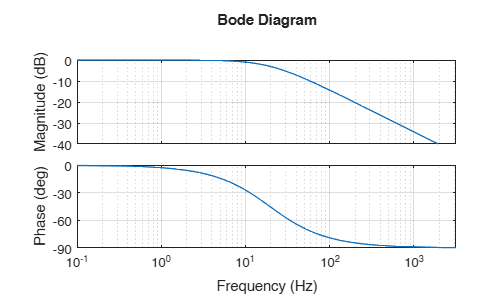

R3 = 12e3;
R4 = 1e-3;
C2 = 680e-9;

tau_1 = R4*C2;
tau_2 = (R3+R4)*C2;
H_lf = (1+tau_1*s)/(1+tau_2*s);
figure;
bode(H_lf,opts);
grid on

Fh = gcf;                                                   % Handle To Current Figure
Kids = Fh.Children;                                         % Children
AxAll = findobj(Kids,'Type','Axes');                        % Handles To Axes

Ax1 = AxAll(1);                                             % First Set Of Axes
LinesAx1 = findobj(Ax1,'Type','Line');                      % Handle To Lines
LinesAx1.LineWidth = 3;                                  % Set ‘LineWidth’

Ax2 = AxAll(2);                                             % Second Set Of Axes
LinesAx2 = findobj(Ax2,'Type','Line');                      % Handle To Lines
LinesAx2.LineWidth = 3;  